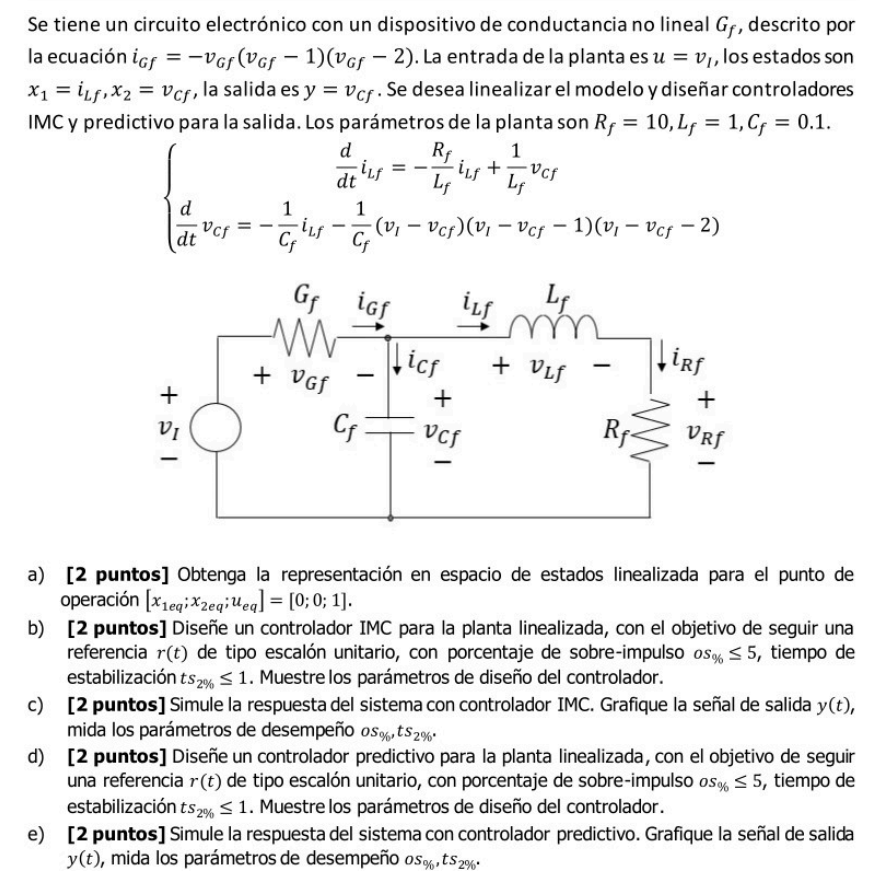

clear all
close all
%Valores:
Rf=10; Lf=1; Cf=0.1;
s=tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


% Estados y entradas
syms x1 x2 u
%% Funciones:
f1=-Rf/Lf*x1+1/Lf*x2;
f2=-1/Cf*x1-(1/Cf)*(u-x2)*(u-x2-1)*(u-x2-2);
f=[f1;f2];
%% Jacobianos:
Jx=jacobian(f,[x1,x2]);
Ju=jacobian(f,u);
% Puntos de Equilibrio
x1_eq = 0; x2_eq = 0; u_eq = 1;
% Evaluación en el Punto de Equilibrio
A=double(subs(Jx, {x1, x2, u}, {x1_eq, x2_eq, u_eq}));
B=double(subs(Ju, {x1, x2, u}, {x1_eq, x2_eq, u_eq}));
% Espacio de Estados Linealizado
C=[0 1]; % Voltaje capacitor
D=[0];
Sp=ss(A,B,C,D)


Sp =
 
  A = 
        x1   x2
   x1  -10    1
   x2  -10  -10
 
  B = 
       u1
   x1   0
   x2  10
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Propertie

Gp=zpk(tf(Sp)) % Planta


Gp =
 
      10 (s+10)
  -----------------
  (s^2 + 20s + 110)
 
Continuous-time zero/pole/gain model.
Model Properties


%% CONTROLADOR IMC
Gm=Gp % Modelo fisico


Gm =
 
      10 (s+10)
  -----------------
  (s^2 + 20s + 110)
 
Continuous-time zero/pole/gain model.
Model Properties


%% Toda la planta es estable por tanto:
Gm_=Gm


Gm_ =
 
      10 (s+10)
  -----------------
  (s^2 + 20s + 110)
 
Continuous-time zero/pole/gain model.
Model Properties


lamda=0.1;
gamma=0;
n=2;
F=(gamma*s+1)/((lamda*s+1)^n)


F =
 
           1
  --------------------
  0.01 s^2 + 0.2 s + 1
 
Continuous-time transfer function.
Model Properties


Q=inv(Gm_)*F


Q =
 
  10 (s^2 + 20s + 110)
  --------------------
        (s+10)^3
 
Continuous-time zero/pole/gain model.
Model Properties


Gc= minreal(feedback(Q,Gm,+1))


Gc =
 
  10 (s^2 + 20s + 110)
  --------------------
    s (s+20) (s+10)
 
Continuous-time zero/pole/gain model.
Model Properties


Gt=feedback(Gc*Gp,1)


Gt =
 
  100 (s+10) (s^2 + 20s + 110)
  ----------------------------
   (s+10)^3 (s^2 + 20s + 110)
 
Continuous-time zero/pole/gain model.
Model Properties


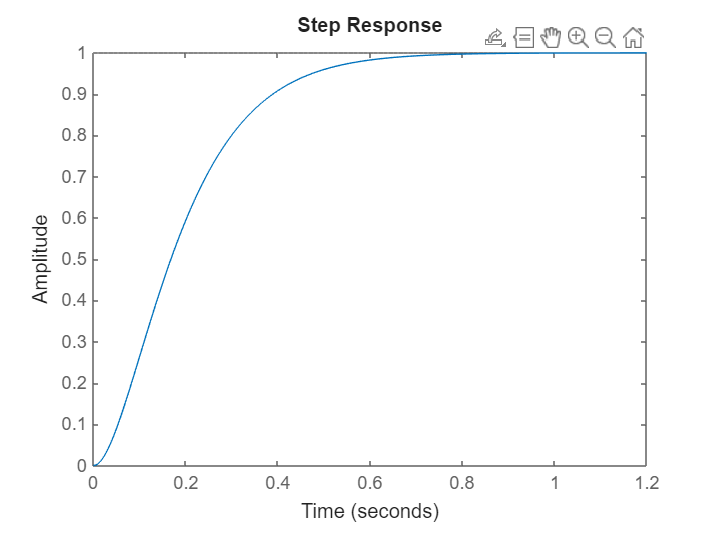

%Graficas
step(Gt)

stepinfo(Gt)

ans = struct with fields:
         RiseTime: 0.3358
    TransientTime: 0.5834
     SettlingTime: 0.5834
      SettlingMin: 0.9019
      SettlingMax: 0.9999
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9999
         PeakTime: 1.1927
